clearvars; close all; clc

% add helper functions to path
addpath(genpath('func'));
% addpath(genpath('eeglab-develop'));

% 参数设置
% 获取目标导联的索引
channame_full = ["Fp1","Fp2","Fz","F3","F4","F7","F8","FC1","FC2","FC5","FC6","Cz","C3","C4","T7","T8","CP1","CP2","CP5","CP6","Pz","P3","P4","P7","P8","Oz","O1","O2"];
channame_target1 = ["Fp1","Fp2","Fz"];
channame_target2 = ["C3","C4","CP1","CP2","CP5","CP6","Pz","P3","P4","P7","P8","Oz","O1","O2"];
chan_tar_ind=zeros([1,length(channame_target2)]);
chan_index = 'O';% channel index: FP or O
for i=1:length(channame_target2)
    chan_tar_ind(i)=find(channame_full==channame_target2(i));
end
% 频段
f_low=2;f_high = 15;
% 时间位移最大量
T=10;

% 导入数据
% 导入index序列
data_sorc = 'data_sub40';
load(strcat(data_sorc,'/idx_files/idx_coo_state1.mat'));
load(strcat(data_sorc,'/idx_files/idx_coo_state2.mat'));
% load(strcat(data_sorc,'/idx_files/idx_coo_state1_inv.mat'));
% load(strcat(data_sorc,'/idx_files/idx_coo_state2_inv.mat'));
statenum = "state1";
subclass = "child";% adult or child
if subclass=="adult"
    if statenum == "state1"
        idx_coo_sub=idx_coo_state1;
        f_target=[6,7,8];
    elseif statenum == "state2"
        idx_coo_sub=idx_coo_state2;
        f_target=[3,4];
        %f_target=[6,7];
    end
elseif subclass=="child"
    if statenum == "state1"
        idx_coo_sub=idx_coo_state1;
        f_target=[6,7,8];
    elseif statenum == "state2"
        idx_coo_sub=idx_coo_state2;
        f_target=[3,4,5];
    end
end
% 导入EEG数据
path_data = 'data_sub40\eegdata_dynamic';
addpath(genpath('data_sub40\eegdata_dynamic'));
Files = dir(fullfile([path_data,'\*.mat']));
LengthFiles = length(Files);

% STFT
eeg_cont=[];
state_cont=[];
% 遍历所有文件
t=1;
for i=1:LengthFiles
    % 导入EEG序列
    file_name=Files(i).name;
    load(file_name);
    % 根据组别导入对应的数据   
    if subclass == "adult"
        eeg_sub = eeg_a;
    elseif subclass == "child"
        eeg_sub = eeg_c;
    end    
    num_tangram=length(eeg_sub);
   
    for nt=1:num_tangram
        % 采用去尾法删除多余
        step=100;%步长
        window=1000;
        sel_eeg=eeg_sub{nt,1};
        data_length=size(sel_eeg,2);
        data_length=data_length-mod(data_length,step);
        num_trail=(data_length-window)/step+1;
        % 如果数据非空
        if data_length>0          
            % 拼接EEG数据
            data_length=data_length-mod(data_length,step);
            eeg_persv = sel_eeg(chan_tar_ind,1:data_length);
            eeg_persv_mean = mean(eeg_persv,1);
            eeg_cont=[eeg_cont;eeg_persv_mean'];
            % 扩充state数据
            state_expd = zeros([1,data_length]);
            % 对应的state序列
            idx_cor = idx_coo_sub(t:t+num_trail-1);
            for st=1:length(idx_cor)
                state_expd((st-1)*100+1:st*100)=idx_cor(st);
            end
            state_expd(st*100+1:data_length)=idx_cor(st);
        end 
        state_cont=[state_cont;state_expd'];
        t=t+num_trail;
    end
end
eeg_cont=eeg_cont';

% fn_sav = strcat("eeg_cont.mat");
% save(fn_sav,"eeg_cont")

% 用的是EEGLAB的newtimf函数，里面的timewarp和timewarpms参数不用管，
% 输入数据格式的话你就仿照平常我们做预处理的EEG结构体来写，
% 返回的ersp是换算为dB后的矩阵，times是输出时频矩阵中时间点序列（滑动窗的中心时刻），
% freqs是频率点序列，cycle参数与滑动窗taper有关，里面默认使用的是Hanning窗，
% 几阶的忘了。padratio控制滑动窗的长度（补零）这个和cycle也有关系，具体看帮助文档吧
k=2;
eeg_cont_k = eeg_cont((k-1)*100+1:(k-1)*100+100);

% [P,R,mbase,timesout,freqs,Pboot,Rboot,alltfX,PA] = newtimef(data, frames, tlimits, Fs, varwin, varargin)
% [ERP,R,mbase,timesout,freqs,Pboot,Rboot,alltfX,PA] = newtimef(eeg_cont_k, 100, [1,100], 1000, 0);

% STFT
% 时频分析参考：
% https://blog.csdn.net/lanchunhui/article/details/72240693
fs = 1000;
win_sz = 1000;
han_win = hamming(win_sz);      % 选择海明窗

nfft = win_sz;
nooverlap = win_sz-1;

P_stft_ft=[];
T_actual_ft=[];
k_fold = 50;
for i=1:k_fold
    eeg_cont_selct = eeg_cont((i-1)*length(eeg_cont)/k_fold+1:i*length(eeg_cont)/k_fold);
    [S, F_stft, T_stft, PSD_stft] = spectrogram(eeg_cont_selct, han_win, nooverlap, nfft, fs);
    T_actual = T_stft*fs+(i-1)*length(eeg_cont)/k_fold;
    T_actual = int64(T_actual);
    T_actual_ft=[T_actual_ft;T_actual'];
    % 获得功率，并选择目标频段
    P_stft=real(PSD_stft/win_sz);
    P_stft=abs(S/win_sz);
%     P_stft_ft = P_stft(:,:);
    P_stft_ft=[P_stft_ft;P_stft'];
    
end
P_stft_ft=P_stft_ft';
% 进一步掐头去尾
% P_stft_ft(:,1:win_sz/2+1)=[];
% P_stft_ft(:,end-win_sz/2+1:end)=[];

% f_target=(0:29)+60;
P_stft_tgt=P_stft_ft(f_target+1,:);

% 确定阶跃时间点
% state文件也对应地掐头去尾
% state_cont(1:win_sz)=[];
% state_cont(end-win_sz+1:end)=[];
% 对idx文件做微分
state_cont_mid = state_cont(T_actual_ft);
idx_coo_sub1 = state_cont_mid;
idx_coo_sub1(1)=[];
idx_coo_sub2 = state_cont_mid;
idx_coo_sub2(length(state_cont_mid))=[];
idx_coo_subd = idx_coo_sub2-idx_coo_sub1;
% 得到阶跃时间点对应的索引
id_up = find(idx_coo_subd==1);
id_down = find(idx_coo_subd==-1);

id_up_selct = id_up(1:end-10);
id_down_selct = id_down(1:end-10);

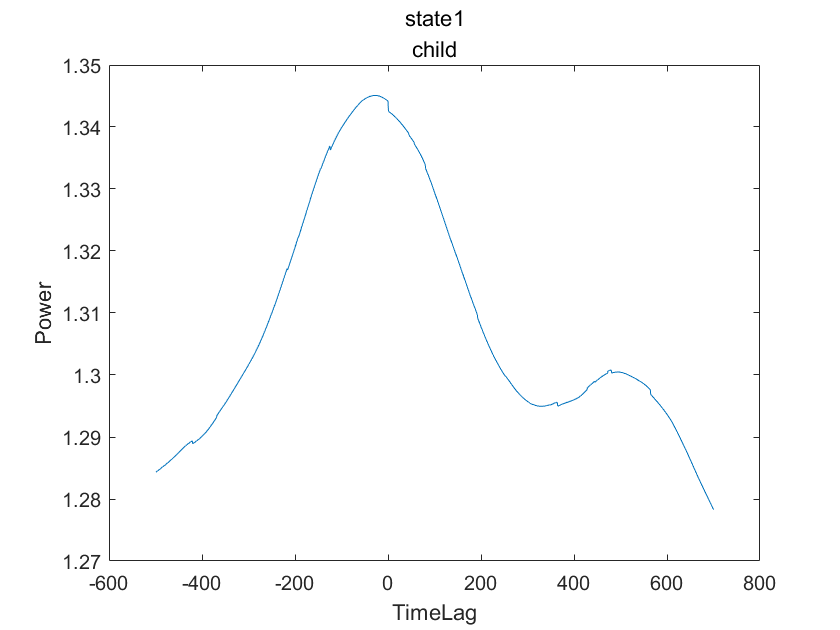

% 设定时间点前后时间窗
W_fl=[-499,700];
P_up=zeros([size(P_stft_tgt,1),W_fl(2)-W_fl(1)+1,length(id_up_selct)]);
P_down=zeros([size(P_stft_tgt,1),W_fl(2)-W_fl(1)+1,length(id_up_selct)]);
% 同一类型的时间窗内脑电信号叠加平均
for i=1:length(id_up_selct)
    P_up(:,:,i)=P_stft_tgt(:,id_up_selct(i)+W_fl(1):id_up_selct(i)+W_fl(2));
end
P_up_mean=mean(P_up,[1,3]);
for i=1:length(id_down_selct)
    P_down(:,:,i)=P_stft_tgt(:,id_down_selct(i)+W_fl(1):id_down_selct(i)+W_fl(2));
end
P_down_mean=mean(P_down,[1,3]);
% 绘制波形图
Xl = zeros([W_fl(2)-W_fl(1)+1,1]);
for l=1:W_fl(2)-W_fl(1)+1
    Xl(l)=l+W_fl(1)-1;
end
plot(Xl,P_up_mean);
title([statenum,subclass]);
xlabel('TimeLag');
ylabel('Power');

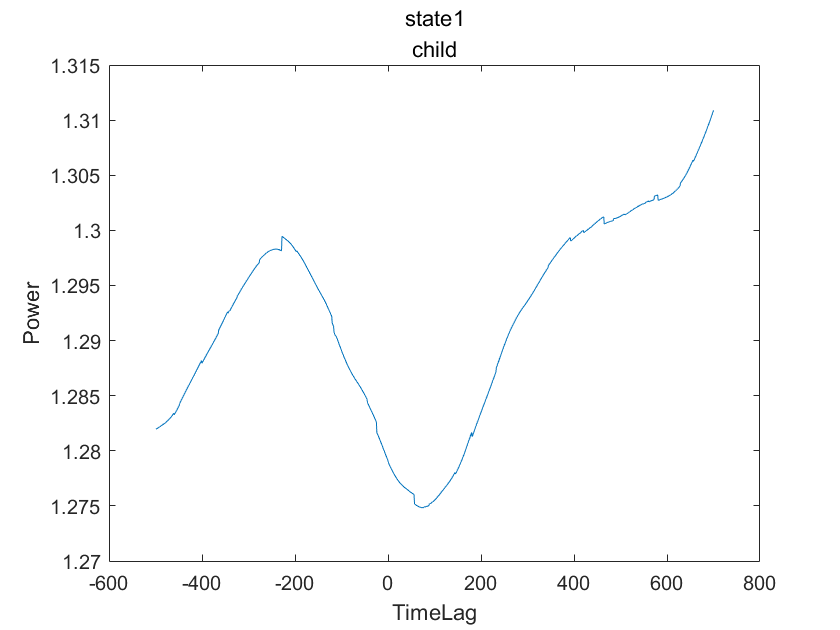

plot(Xl,P_down_mean);
title([statenum,subclass]);
xlabel('TimeLag');
ylabel('Power');

% 曲线平滑一下

% P_down_mean1=mean(P_down,3);
% h = heatmap(P_down_mean1(1:10,100:300));

% 保存文件
% 绘制时频图
% fn_sav = strcat("results_",data_sorc,"/",chan_index,"/tf_",subclass,"_",statenum,".mat");
% save(fn_sav,"sperm_all_mean")
% h = fun_draw_heatmap(sperm_all_mean,T,f_low,f_high,[statenum,subclass],-0.06,0.06);